close all
clear all

## transmit wave

key = [1, 1, 1, -1, -1, -1, 1, -1, -1, 1, 1, -1, 1, -1, 1];
bits = [0,1,0,0,1,0,0,1,0,0,1,0,0,0,0,0,0,1,1,0,0,1,0,0,0,1,1,0,1,1,1,1,0,1,1,0,1,1,1,0,0,0,1,0,0,1,1,1,0,1,1,1,0,1,0,0,0,0,1,0,0,0,0,0,0,1,1,0,1,0,1,1,0,1,1,0,1,1,1,0,0,1,1,0,1,1,1,1,0,1,1,1,0,1,1,1,0,0,1,0,0,0,0,0,0,1,1,1,1,0,0,1,0,1,1,0,1,1,1,1,0,1,1,1,0,1,0,1,0,0,1,0,0,0,0,0,0,1,1,1,0,1,0,0,0,1,1,0,0,1,0,1,0,1,1,0,1,1,0,0,0,1,1,0,1,1,0,0,0,0,1,0,0,0,0,0,0,1,1,0,1,1,0,1,0,1,1,0,0,1,0,1,0,0,1,0,0,0,0,0,0,1,1,0,0,1,0,1,0,1,1,0,0,1,1,1,0,1,1,0,0,1,1,1,0,1,1,0,0,1,0,1,0,1,1,1,0,0,1,0,0,1,1,1,0,1,0,0,0,0,1,0,0,0,0,1];
%bits = [0,1,0,0,1,0,0,1,0,0,1,0,0,0,0,0,0,1,1,0,0,1,0,0,0,1,1,0,1,1,1,1,0,1,1,0,1,1,1,0,0,0,1,0,0,1,1,1,0,1];

FS = 5000000;
FC = 1000000; %920000;
RS = 50000;
sps = FS/RS;

% RRC setup
span = 5;           % number of symbols to truncate RRC
rolloff = 1;      % parameter of RRC
RRC = rcosdesign(rolloff, span, sps, 'sqrt');

%transmit=readmatrix('data/stm_buffer_7.csv');
%transmit = [2577 3566 2562 263 643 3581 3919 1521 512 1519 2631 3585 2429 260 687 3614 3899 1409 386 1548 2717 3550 2193 300 775 3664 3805 1246 355 1696 2877 3254 1805 523 1025 3612 3537 1037 503 1925 3053 2716 1557 859 1450 3370 3138 1108 929 2138 2902 2376 1635 1355 1807 2818 2703 1600 1532 2156 2415 2197 2018 1948 2050 2139 2086 2206 2277 2018 1843 1943 2273 2617 2333 1357 1451 2899 3020 1516 1244 1863 2704 3103 2531 716 932 3450 3601 1396 859 1714 2879 3446 2691 352 661 3734 3889 1473 717 1673 2945 3575 2760 296 629 3791 3905 1605 753 1773 2901 3492 2758 430 761 3619 3711 1709 919 1854 2703 3286 2652 700 971 3327 3443 1819 1057 1805 2523 3114 2501 871 1108 3149 3295 1842 1103 1747 2435 3075 2453 870 1099 3131 3341 1759 1028 1661 2419 3192 2491 691 948 3224 3559 1612 855 1550 2487 3404 2583 403 734 3415 3819 1520 682 1492 2557 3558 2656 269 623 3512 3933 1509 626 1444 2563 3552 2654 335 683 3427 3797 1583 783 1566 2541 3304 2555 698 991 3079 3356 1742 1165 1799 2455 2843 2266 1343 1565 2639 2651 1959 1757 2031 2229 2219 2117 2152 2149 1959 1904 2253 2455 2116 1722 1687 2057 2816 2404 1274 1309 2515 3046 2079 1195 1278 2109 3283 2443 727 869 2809 3592 1863 739 1051 2257 3564 2543 374 647 2991 3894 1627 509 983 2381 3648 2554 220 576 3159 4045 1414 412 1059 2569 3571 2444 226 619 3316 4021 1335 482 1241 2727 3536 2524 254 639 3404 3959 1337 626 1453 2827 3456 2615 425 756 3536 3719 1403 919 1807 2837 3204 2609 850 1103 3200 3235 1733 1373 1956 2511 2715 2353 1583 1713 2382 2406 2056 2015 2111 2074 1867 1991 2582 2539 1554 1373 2491 2853 2506 1869 1119 1763 3433 3214 997 592 2818 3411 2722 1650 677 1713 3875 3545 661 291 2828 3527 2709 1561 703 1653 3728 3399 858 597 2579 3154 2524 1716 1186 1737 3026 2831 1470 1373 2269 2523 2211 1989 1944 2053 2069 2027 2279 2381 1960 1705 1902 2302 2765 2359 1112 1259 2948 3207 1668 1019 1574 2467 3345 2590 463 755 3428 3847 1532 659 1446 2583 3620 2694 222 581 3602 4007 1527 599 1439 2583 3597 2673 303 661 3511 3857 1582 723 1580 2582 3405 2532 528 860 3317 3603 1643 857 1677 2569 3236 2345 715 1047 3205 3392 1609 876 1723 2599 3037 2160 814 1157 3216 3313 1470 818 1769 2727 2866 1941 822 1209 3308 3328 1335 719 1801 2852 2855 1799 780 1221 3404 3361 1187 640 1870 2960 2795 1643 791 1314 3461 3303 1040 663 2009 3047 2559 1519 879 1488 3448 3198 957 748 2180 3095 2382 1463 969 1690 3436 3129 898 803 2349 3207 2305 1453 988 1785 3499]
%transmit = [3197 1762 1101 1749 2579 3292 2487 609 915 3423 3725 1616 689 1623 2659 3552 2448 357 759 3618 3893 1476 479 1595 2735 3595 2283 325 781 3699 3884 1336 380 1646 2829 3508 2039 364 859 3752 3822 1162 305 1742 2955 3367 1757 430 965 3797 3707 961 325 1898 3111 3074 1575 627 1195 3696 3484 986 614 2094 3131 2624 1581 1057 1686 3256 2977 1271 1215 2255 2781 2300 1937 1727 1968 2425 2340 2041 2067 2098 2018 2027 2219 2548 2321 1435 1519 2863 3065 1569 1056 1729 2685 3251 2487 574 834 3444 3885 1376 630 1372 2837 3627 2654 223 629 3559 4091 1373 683 1525 2903 3475 2663 582 903 3442 3523 1506 1247 1975 2665 2853 2453 1506 1665 2437 2463 2087 2065 2177 2066 1819 1991 2763 2713 1513 1238 2701 3189 2597 1815 991 1899 3726 3465 852 432 2980 3796 2777 1675 619 1764 4089 3712 698 260 3001 3787 2783 1717 772 1837 3704 3389 1099 751 2776 3213 2597 1904 1394 1852 2843 2679 1722 1677 2219 2330 2169 2100 2187 2167 1847 1857 2517 2663 1909 1543 1847 2395 2977 2443 945 1137 3284 3490 1781 910 1759 2591 3481 2638 393 704 3618 3947 1601 612 1726 2693 3669 2695 239 602 3674 4015 1569 625 1714 2645 3600 2673 399 744 3487 3844 1630 822 1634 2563 3435 2618 636 931 3288 3625 1693 997 1635 2489 3250 2565 828 1079 3129 3439 1727 1111 1686 2472 3157 2533 884 1118 3087 3399 1715 1108 1694 2504 3188 2545 803 1047 3160 3495 1682 1008 1664 2546 3306 2590 648 919 3295 3655 1647 883 1616 2575 3405 2628 541 836 3402 3747 1636 827 1603 2600 3454 2627 505 823 3429 3751 1647 824 1656 2615 3396 2535 607 931 3319 3600 1699 943 1732 2589 3211 2422 865 1157 3077 3287 1782 1171 1826 2515 2896 2223 1247 1505 2834 2871 1850 1501 1960 2421 2576 2103 1649 1831 2544 2527 1972 1838 2111 2318 2288 2118 2012 2087 2242 2217 2134 2133 2149 2130 2120 2163 3578 2764 637 769 2859 3745 1944 758 1073 2290 3594 2567 493 753 3020 3809 1688 666 1180 2448 3489 2406 544 831 3106 3740 1560 693 1348 2535 3347 2315 678 950 3130 3549 1536 795 1573 2608 3184 2320 838 1071 3131 3408 1509 932 1754 2687 3107 2432 890 1105 3215 3405 1481 1037 1839 2767 3178 2551 798 1028 3384 3568 1458 989 1819 2877 3364 2682 596 867 3638 3815 1480 853 1731 2971 3565 2773 370 687 3822 3967 1575 751 1737 2987 3611 2799 350 676 3793 3895 1676 811 1835 2841 3430 2742 620 915 3441 3530 1841 1117 1885 2557 3019 2491 1190 1395 2805 2893 1932 1631 1970 2267 2414 2215 1950 2015 2145 2131 2161 2241 2207 2038 1791 1988 2710 2638 1535 1370 2400 2827 2430 1798 1209];
%transmit = [2841 3344 1987 471 935 3704 3779 1223 349 1717 2909 3445 1921 380 885 3768 3811 1136 299 1732 2943 3385 1796 372 898 3823 3770 959 246 1811 3036 3248 1622 443 1000 3770 3643 936 341 1896 3092 3000 1546 637 1215 3636 3405 923 607 2102 3111 2516 1507 1003 1663 3281 2991 1160 1078 2237 2855 2297 1687 1519 1899 2684 2575 1774 1724 2169 2310 2159 2087 2162 2144 1907 1915 2377 2505 1976 1706 1875 2403 2772 2386 1235 1369 2953 3118 1547 1063 1765 2685 3168 2439 742 979 3309 3669 1432 762 1572 2795 3430 2563 438 759 3485 3911 1375 682 1479 2865 3554 2658 282 649 3637 4005 1345 651 1471 2915 3562 2695 276 639 3722 3965 1380 697 1585 2939 3574 2723 290 639 3750 3923 1449 750 1678 2935 3498 2727 436 751 3633 3715 1567 960 1859 2823 3213 2646 831 1085 3195 3221 1844 1333 1927 2449 2714 2331 1590 1727 2399 2417 2071 2031 2130 2086 1919 2026 2578 2543 1596 1421 2492 2871 2558 1900 1157 1805 3534 3317 1007 585 2910 3541 2801 1692 645 1761 4030 3685 634 207 2980 3755 2793 1623 637 1754 3847 3502 878 537 2742 3307 2639 1817 1209 1779 3003 2807 1555 1486 2249 2431 2176 2061 2145 2145 1814 1819 2553 2727 1867 1415 1786 2429 3123 2511 687 920 3427 3765 1665 653 1729 2749 3712 2721 116 463 3881 4095 1541 463 1684 2751 3676 2687 300 673 3492 3767 1682 897 1683 2431 3037 2431 1208 1425 2653 2741 1985 1822 2062 2151 2082 2082 2417 2411 1675 1510 2352 2763 2432 1772 1131 1686 3568 3330 817 497 2634 3513 2695 1527 552 1528 4095 3775 471 118 2748 3705 2723 1498 576 1477 3943 3568 751 480 2498 3237 2510 1707 1202 1801 3008 2815 1571 1503 2247 2407 2164 2078 2146 2141 1813 1821 2567 2737 1875 1428 1789 2455 3121 2519 684 919 3347 3762 1551 682 1466 2605 3703 2725 110 483 3712 4095 1471 484 1476 2633 3671 2706 302 675 3405 3763 1635 934 1691 2515 3039 2459 1208 1429 2692 2743 1983 1827 2065 2148 2048 2069 2447 2433 1659 1492 2399 2839 2443 1804 1148 1767 3524 3290 895 560 2571 3515 2695 1572 639 1557 4040 3686 592 220 2627 3687 2717 1511 666 1602 3845 3481 843 585 2561 3309 2530 1611 1200 1829 3079 2737 1501 1443 2314 2551 2214 1978 1999 2097 2057 2031 2320 2407 1950 1662 1949 2391 2697 2123 1195 1419 3006 3141 1602 923 1757 2683 3117 2135 639 1011 3484 3636 1389 499 1664 2797 3415 2039 402 865 3694 3797 1203 316 1691 2891 3421 1868 363 879 3762 3785 1090 281 1756 2977 3362 1767 399 929 3797 3780 1057 286 1790 3011 3334 1734 426 961 3781 3735 1064 333 1813 3009 3180 1690 573 1083 3618 3535 1147];
%transmit = [2638 416 748 3465 3767 1653 810 1683 2519 3320 2551 717 997 3173 3415 1777 1132 1750 2359 2945 2418 1228 1421 2738 2877 1933 1645 1981 2283 2432 2238 1929 1997 2190 2183 2171 2254 2218 2047 1798 2003 2715 2645 1553 1373 2332 2845 2438 1799 1204 1762 3384 3173 999 729 2486 3263 2586 1619 795 1539 3820 3507 701 358 2588 3526 2662 1547 637 1455 3953 3602 643 291 2591 3541 2655 1565 696 1497 3839 3502 763 428 2526 3389 2603 1639 887 1651 3585 3295 975 717 2457 3151 2535 1719 1080 1753 3372 3129 1134 896 2449 3055 2500 1756 1151 1777 3324 3099 1147 895 2477 3086 2520 1735 1065 1741 3464 3215 1005 718 2519 3291 2590 1653 867 1666 3722 3426 791 437 2559 3509 2665 1555 686 1587 3923 3582 662 309 2597 3631 2703 1503 661 1593 3943 3585 717 398 2594 3555 2661 1541 847 1697 3657 3277 995 772 2557 3217 2502 1645 1267 1859 3075 2731 1477 1399 2354 2660 2254 1901 1858 2076 2296 2197 2109 2161 2067 1951 2038 2275 2448 2103 1552 1695 2728 2833 1796 1305 1852 2511 2904 2179 969 1250 3184 3341 1559 807 1730 2715 3219 2147 591 983 3520 3665 1378 489 1663 2794 3439 2099 391 844 3682 3828 1282 347 1639 2825 3528 2043 304 799 3750 3852 1238 322 1673 2865 3459 1934 355 855 3736 3819 1195 319 1695 2889 3394 1888 431 922 3669 3712 1221 435 1751 2901 3128 1858 699 1154 3403 3373 1358 847 1889 2793 2691 1883 1277 1611 2819 2731 1731 1609 2098 2366 2234 2097 2111 2145 1950 1911 2366 2592 2031 1569 1649 2169 2987 2386 1029 1121 2712 3255 2086 956 1062 2139 3644 2773 447 617 2861 3879 1951 626 899 2193 3737 2750 400 655 2938 3789 1787 743 1215 2336 3272 2309 963 1167 2726 3037 1846 1471 1780 2258 2487 2245 1860 1961 2141 2093 2158 2289 2241 1998 1645 1877 2832 2800 1299 1140 2220 2998 2374 1494 925 1565 3622 3324 739 458 2200 3289 2741 1362 551 1241 3993 3582 506 223 2265 3383 2811 1355 534 1275 4017 3556 525 315 2375 3424 2536 1382 731 1563 3772 3392 672 580 2525 3466 2340 1437 935 1827 3583 3246 781 769 2604 3391 2309 1498 1030 1902 3447 3165 838 823 2655 3365 2364 1567 1046 1919 3479 3200 853 806 2704 3439 2426 1608 1007 1919 3572 3266 823 735 2736 3503 2473 1627 959 1900 3639 3299 870 695 2783 3488 2545 1694 974 1900 3542 3254 977 739 2787 3396 2565 1745 1024 1895 3460 3197 1068 795 2779 3328 2573 1778 1046 1887 3445 3191 1096 781 2802 3335 2626 1794 983 1861 3541 3284 1031 649 2862 3453 2708 1756 835 1824 3718 3452 864 427 2935 3615 2766 1680 646 1758 3963 3629 685 239 2982 3751 2788 1636 589 1739 3981 3629 716 305 2931 3607 2764 1706 805 1799 3632 3329 1092 761 2714 3197 2593 1882 1367 1839 2903 2739 1670 1610 2253 2415 2196 2101 2163 2165 1882 1909 2490 2625 1934 1589 1871 2393 2955 2437 969 1164 3274 3473 1790 917 1768 2601 3466 2631 394 716 3598 3903 1626 642 1738 2651 3558 2644 391 738 3465 3747 1669 853 1682 2475 3180 2487 958 1215 2922 3047 1845 1497 1919 2293 2475 2231 1899 2003 2112 2060 2178 2319 2236 1983 1655 1927 2856 2771 1382 1177 2357 2929 2467]
%transmit = [3652, 476, 80, 2859, 3959, 2643, 1519, 506, 1633, 4052, 3637, 671, 275, 2882, 3639, 2655, 1729, 964, 1847, 3262, 3017, 1341, 1168, 2405, 2630, 2231, 1939, 1884, 2021, 2074, 2039, 2259, 2373, 1916, 1622, 1848, 2305, 2874, 2390, 883, 1072, 3318, 3501, 1706, 770, 1734, 2677, 3570, 2645, 130, 485, 3805, 4095, 1507, 406, 1626, 2753, 3701, 2674, 132, 522, 3599, 3887, 1562, 693, 1650, 2464, 3200, 2470, 894, 1164, 2853, 2965, 1843, 1541, 1931, 2219, 2276, 2135, 2081, 2118, 1892, 1785, 2236, 2519, 2306, 1841, 1301, 1759, 3204, 3083, 933, 648, 2480, 3303, 2583, 1513, 589, 1409, 4013,3658, 449, 64, 2651, 3667, 2683, 1440, 453, 1379, 4006, 3623, 584, 257, 2507, 3387, 2543, 1606, 955, 1677, 3257, 2995, 1299, 1163, 2324, 2651, 2220, 1938, 1884, 2017, 2027, 2003, 2292, 2403, 1915, 1608, 1851, 2351, 2864, 2367, 913, 1105, 3083, 3453, 1621, 784, 1586, 2581, 3496, 2454, 243, 638, 3619, 3936, 1428, 371, 1501, 2687, 3586, 2260, 297, 759, 3542, 3705, 1399, 592, 1686, 2691, 2947, 2039, 960, 1323, 2919, 2839, 1631, 1386, 1965, 2359, 2260, 1995, 1917, 2003, 2026, 1980, 2191, 2336, 1983, 1677, 1718, 2095, 2762, 2292, 1166, 1255, 2597, 3115, 1909, 991, 1236, 2212, 3340, 2390, 541, 761, 2908, 3719, 1703, 592, 999, 2320, 3618, 2566, 269, 593, 3034, 3971, 1527, 449, 998, 2447, 3619, 2495, 212, 581, 3186, 4017, 1388, 418, 1089, 2571, 3556, 2432, 218, 603, 3289, 4007, 1326, 454, 1202, 2691, 3524, 2476, 237, 623, 3341, 3949, 1319, 570, 1380, 2777, 3425, 2559, 397, 726, 3492, 3685, 1366, 886, 1775, 2802, 3166, 2573, 812, 1061, 3157, 3194, 1695, 1333, 1917, 2472, 2677, 2321, 1547, 1678, 2349, 2372, 2025, 1985, 2083, 2044, 1873, 1977, 2526, 2491, 1551, 1366, 2487, 2865, 2482, 1853, 1077, 1781, 3456, 3235, 933, 510, 2862, 3475, 2728, 1629, 582, 1695, 3978, 3633, 570, 163, 2913, 3673, 2743, 1538, 601, 1687, 3813, 3463, 790, 505, 2603, 3187, 2537, 1703, 1173, 1726, 2963, 2767, 1519, 1451, 2212, 2391, 2132, 2023, 2136, 2114, 1742, 1755, 2529, 2700, 1811, 1387, 1748, 2319, 3050, 2449, 689, 915, 3256, 3651, 1527, 696, 1485, 2535, 3574, 2644, 172, 531, 563, 3993, 1463, 550, 1461, 2563, 3544, 2641, 374, 716, 3302, 3653, 1613, 941, 1660, 2471, 3003, 2429, 1130, 1342, 2718, 2802, 1905, 1667, 1969, 2171, 2224, 2115, 2098, 2132, 1884, 1791, 2215, 2487, 2264, 1829, 1414, 1829, 3018, 2853, 1151, 909, 2491, 3079, 2506, 1469, 827, 1653, 3709, 3297, 661, 396, 2561, 3638, 2539, 1139, 596, 1661, 3933, 3376, 428, 292, 2632, 3787, 2363, 887, 681, 1815, 3802, 3055, 454, 503, 2693, 3687, 2117, 812, 909, 2036, 3540, 2636, 573, 756, 2804, 3556, 1832, 803, 1204, 2272, 3270, 2304, 749, 970, 2878, 3392, 1675, 871, 1428, 2402, 3124, 2236, 824, 1041, 2963, 3355, 1533, 826, 1555, 2543, 3117, 2261, 749, 980, 3100, 3455, 1427, 737, 1573, 2651, 3212, 2391, 599, 862, 3301, 3616, 1358, 763, 1616, 2765, 3297, 2538, 498, 783, 3460, 3683, 1346, 809, 1678, 2845, 3359, 2641, 462, 754, 3573, 3683, 1498, 880, 1784, 2843, 3324, 2682, 562, 839, 3484, 3552, 1644, 1028, 1865, 2751, 3162, 2619, 820, 1063, 3215, 3273, 1799, 1214, 1868, 2503, 2895, 2432, 1181, 1366, 2792, 2879, 1892, 1487, 1872, 2263, 2581, 2247, 1551, 1667, 2433, 2503, 1951, 1785, 1978, 2157, 2257, 2135, 1907, 1948, 2152, 2161, 2055, 2042, 2070, 2065, 2027, 2051, 3785, 3251, 809, 507, 2592, 3293, 2584, 1550, 757, 1503, 3707, 3393, 726, 447, 2541, 3316, 2564, 1543, 771, 1474, 3669, 3357, 777, 510, 2470, 3249, 2531, 1578, 847, 1559, 3566, 3273, 893, 640, 2425, 3151, 2501, 1651, 984, 1679, 3419, 3156, 1024, 786, 2410, 3061, 2483, 1696, 1062, 1723, 3341, 3098, 1066, 820, 2427, 3055, 2479, 1687, 1024, 1703, 3403, 3148, 983, 711, 2464, 3195, 2526, 1621, 873, 1645, 3600, 3303, 807, 501, 2514, 3421, 2603, 1437, 671, 1583, 3839, 3447, 620, 320, 2550, 3627, 2586, 1227, 611, 1618, 3888, 3386, 559, 363, 2586, 3639, 2465, 1140, 767, 1738, 3668, 3049, 755, 681, 2578, 3381, 2268, 1229, 1173, 1925, 3098, 2523, 1215, 1263, 2423, 2799, 2039, 1588, 1741, 2074, 2394, 2172, 1896, 1944, 2089, 2075, 2090, 2167, 2169, 1983, 1720, 1883, 2592, 2583, 1485, 1314, 2063, 2722, 2376, 1591, 1099, 1607, 3153, 3091, 934, 677, 2168, 3167, 2512, 1371, 679, 1389, 3802, 3411, 538, 313, 2310, 3372, 2596, 1310, 550, 1335, 3975, 3499, 441, 254, 2439, 3504, 2455, 1316, 642, 1534, 3867, 3418, 530, 417, 2581, 3543, 2306, 1402, 852, 1794, 3582, 3234, 745, 701, 2656, 3371, 2364, 1586, 1036, 1887, 3329, 3081, 1043, 867, 2676, 3219, 2436, 1722, 1098, 1870, 3272, 3058, 1138, 854, 2716, 3207, 2535, 1775, 1012, 1812, 3415, 3174, 1047, 667, 2793, 3341, 2656, 1727, 810, 1761, 3668, 3383, 824, 423, 2849, 3479, 2716, 1637, 638, 1708, 3875, 3545, 620, 220, 2867, 3609, 2729, 1504, 533, 1657, 3971, 3609, 564, 217, 2785, 3509, 2657, 1510, 678, 1566, 3715, 3381, 807, 563, 2492, 3127, 2475, 1662, 1146, 1693, 3048, 2847, 1425, 1313, 2263, 2551, 2207, 1956, 1886, 2019, 2097, 2049, 2219, 2326, 1947, 1721, 1900, 2293, 2708, 2327, 1130, 1275, 2927, 3159, 1665, 1031, 1613, 2493, 3318, 2568, 451, 741, 3428, 3799, 1534, 647, 1450, 2539, 3524, 2601, 287, 648, 3461, 3783, 1566, 697, 1607, 2560, 3268, 2365, 743, 1084, 3026, 3181, 1735, 1223, 1840, 2407, 2597, 2080, 1612, 1808, 2316, 2247, 2072, 2110, 2093, 1916, 1840, 2065, 2589, 2313, 1424, 1401, 2421, 2907, 2130, 1317, 1249, 1975, 3263, 2462, 749, 817, 2693, 3557, 2048, 808, 919, 2051, 3645, 2768, 373, 545, 2810, 3842, 1887, 556, 839, 2147, 3735, 2759, 237, 497, 2917, 3952, 1667, 455, 905, 2305, 3671, 2594, 188, 519, 3090, 4033, 1427, 402, 1029, 2512, 3568, 2430, 233, 619, 3238, 3937, 1344, 498, 1286, 2675, 3406, 2432, 444, 773, 3323, 3685, 1377, 810, 1683, 2747, 3157, 2482, 799, 1051, 3166, 3252, 1468, 1293, 1917, 2583, 2812, 2405, 1341, 1497, 2567, 2647, 1940, 1727, 1963, 2155, 2214, 2108, 2067, 2116, 1932, 1857, 2160, 2359, 2217, 1911, 1578, 1869, 2808, 2721, 1408, 1171, 2574, 2947, 2512, 1844, 1096, 1776, 3373, 3154, 1065];
%transmit = [3652, 476, 80, 2859, 3959, 2643, 1519, 506, 1633, 4052, 3637, 671, 275, 2882, 3639, 2655, 1729, 964, 1847, 3262, 3017, 1341, 1168, 2405, 2630, 2231, 1939, 1884, 2021, 2074, 2039, 2259, 2373, 1916, 1622, 1848, 2305, 2874, 2390, 883, 1072, 3318, 3501, 1706, 770, 1734, 2677, 3570, 2645, 130, 485, 3805, 4095, 1507, 406, 1626, 2753, 3701, 2674, 132, 522, 3599, 3887, 1562, 693, 1650, 2464, 3200, 2470, 894, 1164, 2853, 2965, 1843, 1541, 1931, 2219, 2276, 2135, 2081, 2118, 1892, 1785, 2236, 2519, 2306, 1841, 1301, 1759, 3204, 3083, 933, 648, 2480, 3303, 2583, 1513, 589, 1409, 4013,3658, 449, 64, 2651, 3667, 2683, 1440, 453, 1379, 4006, 3623, 584, 257, 2507, 3387, 2543, 1606, 955, 1677, 3257, 2995, 1299, 1163, 2324, 2651, 2220, 1938, 1884, 2017, 2027, 2003, 2292, 2403, 1915, 1608, 1851, 2351, 2864, 2367, 913, 1105, 3083, 3453, 1621, 784, 1586, 2581, 3496, 2454, 243, 638, 3619, 3936, 1428, 371, 1501, 2687, 3586, 2260, 297, 759, 3542, 3705, 1399, 592, 1686, 2691, 2947, 2039, 960, 1323, 2919, 2839, 1631, 1386, 1965, 2359, 2260, 1995, 1917, 2003, 2026, 1980, 2191, 2336, 1983, 1677, 1718, 2095, 2762, 2292, 1166, 1255, 2597, 3115, 1909, 991, 1236, 2212, 3340, 2390, 541, 761, 2908, 3719, 1703, 592, 999, 2320, 3618, 2566, 269, 593, 3034, 3971, 1527, 449, 998, 2447, 3619, 2495, 212, 581, 3186, 4017, 1388, 418, 1089, 2571, 3556, 2432, 218, 603, 3289, 4007, 1326, 454, 1202, 2691, 3524, 2476, 237, 623, 3341, 3949, 1319, 570, 1380, 2777, 3425, 2559, 397, 726, 3492, 3685, 1366, 886, 1775, 2802, 3166, 2573, 812, 1061, 3157, 3194, 1695, 1333, 1917, 2472, 2677, 2321, 1547, 1678, 2349, 2372, 2025, 1985, 2083, 2044, 1873, 1977, 2526, 2491, 1551, 1366, 2487, 2865, 2482, 1853, 1077, 1781, 3456, 3235, 933, 510, 2862, 3475, 2728, 1629, 582, 1695, 3978, 3633, 570, 163, 2913, 3673, 2743, 1538, 601, 1687, 3813, 3463, 790, 505, 2603, 3187, 2537, 1703, 1173, 1726, 2963, 2767, 1519, 1451, 2212, 2391, 2132, 2023, 2136, 2114, 1742, 1755, 2529, 2700, 1811, 1387, 1748, 2319, 3050, 2449, 689, 915, 3256, 3651, 1527, 696, 1485, 2535, 3574, 2644, 172, 531, 563, 3993, 1463, 550, 1461, 2563, 3544, 2641, 374, 716, 3302, 3653, 1613, 941, 1660, 2471, 3003, 2429, 1130, 1342, 2718, 2802, 1905, 1667, 1969, 2171, 2224, 2115, 2098, 2132, 1884, 1791, 2215, 2487, 2264, 1829, 1414, 1829, 3018, 2853, 1151, 909, 2491, 3079, 2506, 1469, 827, 1653, 3709, 3297, 661, 396, 2561, 3638, 2539, 1139, 596, 1661, 3933, 3376, 428, 292, 2632, 3787, 2363, 887, 681, 1815, 3802, 3055, 454, 503, 2693, 3687, 2117, 812, 909, 2036, 3540, 2636, 573, 756, 2804, 3556, 1832, 803, 1204, 2272, 3270, 2304, 749, 970, 2878, 3392, 1675, 871, 1428, 2402, 3124, 2236, 824, 1041, 2963, 3355, 1533, 826, 1555, 2543, 3117, 2261, 749, 980, 3100, 3455, 1427, 737, 1573, 2651, 3212, 2391, 599, 862, 3301, 3616, 1358, 763, 1616, 2765, 3297, 2538, 498, 783, 3460, 3683, 1346, 809, 1678, 2845, 3359, 2641, 462, 754, 3573, 3683, 1498, 880, 1784, 2843, 3324, 2682, 562, 839, 3484, 3552, 1644, 1028, 1865, 2751, 3162, 2619, 820, 1063, 3215, 3273, 1799, 1214, 1868, 2503, 2895, 2432, 1181, 1366, 2792, 2879, 1892, 1487, 1872, 2263, 2581, 2247, 1551, 1667, 2433, 2503, 1951, 1785, 1978, 2157, 2257, 2135, 1907, 1948, 2152, 2161, 2055, 2042, 2070, 2065, 2027, 2051, 3785, 3251, 809, 507, 2592, 3293, 2584, 1550, 757, 1503, 3707, 3393, 726, 447, 2541, 3316, 2564, 1543, 771, 1474, 3669, 3357, 777, 510, 2470, 3249, 2531, 1578, 847, 1559, 3566, 3273, 893, 640, 2425, 3151, 2501, 1651, 984, 1679, 3419, 3156, 1024, 786, 2410, 3061, 2483, 1696, 1062, 1723, 3341, 3098, 1066, 820, 2427, 3055, 2479, 1687, 1024, 1703, 3403, 3148, 983, 711, 2464, 3195, 2526, 1621, 873, 1645, 3600, 3303, 807, 501, 2514, 3421, 2603, 1437, 671, 1583, 3839, 3447, 620, 320, 2550, 3627, 2586, 1227, 611, 1618, 3888, 3386, 559, 363, 2586, 3639, 2465, 1140, 767, 1738, 3668, 3049, 755, 681, 2578, 3381, 2268, 1229, 1173, 1925, 3098, 2523, 1215, 1263, 2423, 2799, 2039, 1588, 1741, 2074, 2394, 2172, 1896, 1944, 2089, 2075, 2090, 2167, 2169, 1983, 1720, 1883, 2592, 2583, 1485, 1314, 2063, 2722, 2376, 1591, 1099, 1607, 3153, 3091, 934, 677, 2168, 3167, 2512, 1371, 679, 1389, 3802, 3411, 538, 313, 2310, 3372, 2596, 1310, 550, 1335, 3975, 3499, 441, 254, 2439, 3504, 2455, 1316, 642, 1534, 3867, 3418, 530, 417, 2581, 3543, 2306, 1402, 852, 1794, 3582, 3234, 745, 701, 2656, 3371, 2364, 1586, 1036, 1887, 3329, 3081, 1043, 867, 2676, 3219, 2436, 1722, 1098, 1870, 3272, 3058, 1138, 854, 2716, 3207, 2535, 1775, 1012, 1812, 3415, 3174, 1047, 667, 2793, 3341, 2656, 1727, 810, 1761, 3668, 3383, 824, 423, 2849, 3479, 2716, 1637, 638, 1708, 3875, 3545, 620, 220, 2867, 3609, 2729, 1504, 533, 1657, 3971, 3609, 564, 217, 2785, 3509, 2657, 1510, 678, 1566, 3715, 3381, 807, 563, 2492, 3127, 2475, 1662, 1146, 1693, 3048, 2847, 1425, 1313, 2263, 2551, 2207, 1956, 1886, 2019, 2097, 2049, 2219, 2326, 1947, 1721, 1900, 2293, 2708, 2327, 1130, 1275, 2927, 3159, 1665, 1031, 1613, 2493, 3318, 2568, 451, 741, 3428, 3799, 1534, 647, 1450, 2539, 3524, 2601, 287, 648, 3461, 3783, 1566, 697, 1607, 2560, 3268, 2365, 743, 1084, 3026, 3181, 1735, 1223, 1840, 2407, 2597, 2080, 1612, 1808, 2316, 2247, 2072, 2110, 2093, 1916, 1840, 2065, 2589, 2313, 1424, 1401, 2421, 2907, 2130, 1317, 1249, 1975, 3263, 2462, 749, 817, 2693, 3557, 2048, 808, 919, 2051, 3645, 2768, 373, 545, 2810, 3842, 1887, 556, 839, 2147, 3735, 2759, 237, 497, 2917, 3952, 1667, 455, 905, 2305, 3671, 2594, 188, 519, 3090, 4033, 1427, 402, 1029, 2512, 3568, 2430, 233, 619, 3238, 3937, 1344, 498, 1286, 2675, 3406, 2432, 444, 773, 3323, 3685, 1377, 810, 1683, 2747, 3157, 2482, 799, 1051, 3166, 3252, 1468, 1293, 1917, 2583, 2812, 2405, 1341, 1497, 2567, 2647, 1940, 1727, 1963, 2155, 2214, 2108, 2067, 2116, 1932, 1857, 2160, 2359, 2217, 1911, 1578, 1869, 2808, 2721, 1408, 1171, 2574, 2947, 2512, 1844, 1096, 1776, 3373, 3154, 1065,674, 2792, 3333, 2683, 1719, 791, 1747, 3726, 3435, 793, 378, 2853, 3526, 2733, 1599, 616, 1697, 3901, 3564, 612, 231, 2843, 3571, 2711, 1495, 550, 1633, 3938, 3570, 575, 226, 2746, 3511, 2645, 1471, 575, 1545, 3917, 3562, 567, 237, 2619, 3471, 2612, 1486, 634, 1438, 3822, 3478, 678, 383, 2495, 3318, 2538, 1568, 857, 1561, 3485, 3194, 1006, 800, 2356, 2967, 2391, 1766, 1343, 1823, 2826, 2658, 1612, 1545, 2197, 2355, 2134, 2023, 2068, 2081, 1902, 1875, 2406, 2532, 1887, 1543, 1839, 2379, 2904, 2394, 903, 1100, 3099, 3467, 1633, 829, 1596, 2573, 3491, 2522, 256, 628, 3599,3951, 1485, 438, 1463, 2618, 3610, 2411, 248, 689, 3511, 3739, 1471, 614, 1651, 2622, 3022, 2122, 951, 1301, 2879, 2823, 1691, 1462, 1979, 2304, 2211, 2039, 2059, 2102, 1813, 1774, 2317, 2624, 1999, 1371, 1431, 2107, 3134, 2371, 675, 823, 2851, 3725, 1772, 543, 884, 2273, 3774, 2774, 111, 220, 3061, 4095, 1499, 317, 877, 2415, 3684, 2572, 245, 632, 3138, 3779, 1447, 665, 1526, 2565, 2936, 2187, 1170, 1381, 2603, 2692, 1962, 1790, 2010, 2103, 2041, 2037, 2365, 2367, 1649, 1469, 2422, 2865, 2295, 1623, 1064, 1854, 3637, 3255, 626, 448, 2734, 3748, 2545, 1486, 529, 1567, 4095,3687, 418, 65, 2833, 3932, 2626, 1527, 563, 1674, 3884, 3519, 790, 434, 2824, 3421, 2580, 1794, 1156, 1829, 2968, 2775, 1530, 1463, 2200, 2367, 2127, 2039, 2110, 2111, 1783, 1785, 2531, 2698, 1870, 1375, 1771, 2423, 3094, 2491, 652, 887, 3411, 3729, 1633, 617, 1689, 2693, 3669, 2677, 77, 423, 3833, 4095, 1484, 420, 1639, 2683, 3631, 2639, 256, 629, 3407, 3716, 1609, 855, 1599, 2371, 2989, 2384, 1162, 1381, 2603, 2693, 1940, 1777, 2018, 2103, 2001, 2023, 2404, 2387, 1612, 1445, 2267, 2751, 2384, 1735, 1091, 1681, 3462, 3228, 815, 502, 2501, 3419, 2612, 1524, 580, 1419, 3983,3628, 539, 161, 2587, 3602, 2659, 1519, 625, 1488, 3801, 3447, 798, 516, 2470, 3213, 2494, 1697, 1155, 1765, 3035, 2800, 1463, 1377, 2278, 2510, 2181, 1965, 1955, 2051, 2015, 1990, 2278, 2369, 1930, 1652, 1893, 2325, 2704, 2155, 1140, 1349, 2957, 3127, 1638, 934, 1697, 2579, 3157, 2189, 583, 945, 3426, 3601, 1353, 463, 1622, 2753, 3367, 1993, 361, 829, 3659, 3744, 1127, 263, 1681, 2893, 3307, 1702, 351, 899, 3765, 3671, 847, 209, 1846, 3089, 3074, 1443, 417, 1026, 3842, 3583, 623, 203, 2036, 3241, 2864, 1332, 491, 1183, 3908, 3493, 528, 285, 2275, 3324, 2559, 1339, 677,1471, 3754, 3327, 662, 578, 2443, 3335, 2251, 1413, 1051, 1871, 3200, 2957, 1222, 1148, 2441, 2758, 2304, 1933, 1678, 1931, 2374, 2283, 1987, 2013, 2043, 1955, 1969, 2163, 2480, 2240, 1366, 1437, 2902, 2995, 1573, 1215, 1851, 2737, 3209, 2632, 529, 773, 3666, 3779, 1515, 705, 1651, 2933, 3603, 2741, 154, 512, 3837, 3974, 1535, 647, 1711, 2890, 3451, 2724, 514, 823, 3417, 3469, 1771, 1150, 1877, 2493, 2784, 2349, 1451, 1617, 2388, 2405, 2022, 2003, 2117, 2004, 1751, 1931, 2702, 2644, 1384, 1171, 2511, 3030, 2561, 1772, 922, 1655, 3669, 3393, 735, 356, 2810, 3527, 2722, 1504, 523,1643, 4001, 3636, 534, 182, 2800, 3520, 2658, 1511, 702, 1584, 3645, 3316, 909, 689, 2465, 2997, 2411, 1726, 1336, 1801, 2783, 2611, 1664, 1618, 2162, 2271, 2109, 2039, 2128, 2109, 1787, 1798, 2465, 2607, 1864, 1492, 1812, 2343, 2913, 2407, 892, 1079, 3069, 3437, 1595, 876, 1489, 2477, 3412, 2601, 338, 655, 3475, 3890, 1491, 584, 1400, 2553, 3601, 2662, 180, 545, 3566, 3954, 1505, 580, 1431, 2545, 3524, 2614, 324, 675, 3431, 3762, 1571, 744, 1572, 2545, 3346, 2499, 550, 871, 3249, 3527, 1639, 887, 1675, 2529, 3168, 2355, 751, 1061, 3108, 3328, 1655, 945, 1720, 2542, 3010,2179, 855, 1177, 3144, 3261, 1523, 869, 1760, 2677, 2871, 1975, 831, 1211, 3293, 3318, 1342, 692, 1768, 2822, 2911, 1805, 701, 1140, 3465, 3429, 1139, 498, 1802, 2937, 2956, 1660, 612, 1107, 3565, 3469, 985, 423, 1859, 3031, 2927, 1539, 604, 1158, 3619, 3415, 860, 451, 1991, 3094, 2711, 1447, 729, 1354, 3531, 3262, 899, 651, 2111, 3061, 2414, 1467, 985, 1644, 3261, 2967, 1055, 985, 2264, 2917, 2227, 1553, 1339, 1867, 2860, 2747, 1490, 1383, 2268, 2599, 2275, 1929, 1660, 1918, 2506, 2423, 1803, 1744, 2152, 2287, 2155, 2023, 1962, 2039, 2173, 2146, 2059, 2060, 2078, 2060, 2063,2101, 3280, 2581, 534, 805, 3535, 3665, 1401, 850, 1728, 2861, 3372, 2667, 463, 755, 3586, 3687, 1497, 871, 1775, 2853, 3344, 2679, 518, 802, 3536, 3623, 1603, 937, 1828, 2787, 3265, 2658, 635, 902, 3395, 3473, 1716, 1038, 1847, 2632, 3151, 2578, 770, 1021, 3237, 3347, 1798, 1077, 1806, 2518, 3101, 2503, 813, 1052, 3198, 3345, 1806, 1028, 1748, 2489, 3159, 2499, 707, 959, 3261, 3487, 1726, 871, 1686, 2493, 3325, 2542, 485, 779, 3406, 3743, 1577, 671, 1655, 2549, 3518, 2606, 278, 623, 3519, 3908, 1499, 600, 1594, 2567, 3565, 2625, 279, 637, 3451, 3845, 1519, 702, 1489,2495, 3372, 2570, 563, 870, 3153, 3476, 1639, 1039, 1663, 2425, 2956, 2404, 1133, 1339, 2722, 2851, 1876, 1575, 1921, 2237, 2350, 2158, 1889, 1954, 2085, 2068, 2101, 2179, 2150, 1975, 1730, 1935, 2656, 2567, 1484, 1315, 2380, 2832, 2389, 1694, 1151, 1743, 3337, 2998, 971, 715, 2530, 3351, 2522, 1365, 765, 1648, 3764, 3298, 623, 391, 2575, 3655, 2507, 1127, 637, 1676, 3882, 3317, 495, 369, 2621, 3709, 2367, 963, 743, 1813, 3727, 3004, 518, 565, 2688, 3621, 2089, 854, 1011, 2079, 3422, 2514, 703, 873, 2762, 3429, 1891, 932, 1281, 2231, 3174, 2289, 867, 1056, 2789, 3293, 1775,963, 1403, 2321, 3080, 2237, 855, 1055, 2875, 3343, 1635, 851, 1411, 2419, 3191, 2243, 660, 905, 3079, 3571, 1437, 631, 1355, 2581, 3359, 2330, 417, 745, 3236, 3827, 1341, 508, 1261, 2671, 3493, 2462, 213, 596, 3355, 4018, 1298, 491, 1247, 2769, 3539, 2572, 209, 601, 3504, 3902, 1315, 693, 1565, 2838, 3337, 2598, 582, 877, 3371, 3434, 1491, 1187, 1912, 2647, 2867, 2439, 1312, 1484, 2534, 2612, 1966, 1805, 2014, 2121, 2061, 2052, 2333, 2313, 1736, 1601, 2341, 2667, 2396, 1903, 1276, 1811, 3186, 3070, 1089, 739, 2803, 3377, 2673, 1710, 738, 1758, 3792, 3489, 728, 295, 2899,3591, 2729, 1609, 629, 1712, 3796, 3460, 784, 445, 2694, 3305, 2617, 1682, 1008, 1641, 3232, 2978, 1247, 1126, 2321, 2668, 2258, 1895, 1722, 1953, 2289, 2187, 2075, 2127, 2007, 1868, 1950, 2212, 2546, 2261, 1330, 1437, 2761, 2973, 1735, 1190, 1685, 2363, 3134, 2481, 667, 911, 3229, 3603, 1554, 778, 1476, 2488, 3444, 2596, 319, 643, 3434, 3859, 1479, 607, 1427, 2541, 3555, 2643, 228, 582, 3514, 3927, 1495, 591, 1408, 2547, 3572, 2651, 213, 555, 3563, 3951, 1508, 576, 1427, 2553, 3570, 2610, 263, 633, 3527, 3857, 1546, 593, 1568, 2615, 3450, 2344, 459, 855, 3400, 3585, 1485,686, 1679, 2645, 3039, 2101, 830, 1193, 3095, 3121, 1531, 1065, 1847, 2514, 2573, 1938, 1393, 1654, 2610, 2539, 1792, 1683, 2054, 2243, 2127, 2041, 2098, 2101, 1875, 1866, 2285, 2450, 1922, 1641, 1736, 2201, 2735, 2256, 1187, 1307, 2680, 3091, 1709, 977, 1434, 2383, 3166, 2247, 658, 893, 3060, 3607, 1471, 610, 1260, 2525, 3420, 2331, 354, 685, 3232, 3905, 1348, 466, 1201, 2647, 3518, 2453, 227, 611, 3355, 4010, 1316, 501, 1267, 2771, 3513, 2570, 239, 615, 3491, 3958, 1306, 609, 1419, 2845, 3514, 2647, 256, 611, 3654, 3902, 1363, 711, 1618, 2898, 3457, 2687, 399, 712, 3592,3680, 1536, 928, 1829, 2799, 3182, 2616, 806, 1057, 3168, 3197, 1783, 1309, 1905, 2437, 2672, 2294, 1546, 1677, 2346, 2370, 2021, 1982, 2082, 2039, 1873, 1978, 2529, 2490, 1537, 1363, 2416, 2803, 2472, 1813, 1078, 1704, 3459, 3226, 897, 503, 2760, 3421, 2706, 1554, 572, 1660, 3973, 3619, 525, 153, 2838, 3591, 2687, 1481, 602, 1591, 3817, 3462, 759, 509, 2525, 3167, 2501, 1679, 1180, 1719, 2967, 2779, 1530, 1456, 2221, 2400, 2142, 2033, 2110, 2109, 1780, 1782, 2521, 2691, 1823, 1393, 1752, 2349, 3074, 2471, 644, 875, 3299, 3714, 1498, 635, 1483, 2565, 3655, 2676, 68, 437, 3658];
%transmit = matlab_transmit;
%transmit = [2459, 1354, 715, 534, 1114, 2462, 2317, 697, 310, 1133, 1793, 2301, 1808, 306, 299, 1800, 2308, 1799, 1111, 287, 722, 2358, 2426, 1017, 517, 823, 1396, 2344, 2097, 551, 282, 1418, 2061, 2039, 1397, 332, 603, 2015, 2232, 1429, 925, 554, 981, 2332, 2285, 773, 380, 1154, 1735, 2104, 1703, 537, 490, 1611, 2082, 1819, 1206, 369, 749, 2192, 2247, 1104, 700, 814, 1249, 2230, 2109, 673, 337, 1301, 1931, 2031, 1472, 415, 576, 1837, 2147, 1596, 1040, 423, 843, 2311, 2306, 870, 454, 980, 1527, 2214, 1911, 502, 323, 1515, 2089, 1909, 1280, 325, 617, 2060, 2279, 1346, 773, 493, 1040, 2475, 2314, 523, 162, 1272, 1951, 2151, 1563, 192, 339, 2069, 2458, 1345, 631, 563, 1225, 2318, 2004, 606, 479, 1403, 1803, 1771, 1370, 654, 832, 1777, 1845, 1200, 1006, 1150, 1291, 1490, 1486, 1268, 1153, 1189, 1319, 1450, 1368, 1236, 1254, 1271, 1266, 1351, 1365, 1291, 1289, 1300, 1228, 1169, 1331, 1642, 1465, 812, 877, 1680, 1799, 1257, 997, 921, 1134, 1839, 1866, 972, 634, 1092, 1599, 1947, 1554, 568, 609, 1563, 1885, 1710, 1252, 379, 630, 2125, 2287, 1055, 552, 757, 1266, 2183, 2029, 671, 314, 1124, 1802, 2198, 1590, 150, 301, 1905, 2271, 1558, 950, 278, 683, 2339, 2445, 874, 271, 723, 1469, 2453, 2026, 195, 26, 1602, 2285, 1889, 1074, 93, 609, 2330, 2333, 875, 451, 896, 1417, 2077, 1782, 559, 475, 1509, 1866, 1512, 1106, 808, 1046, 1633, 1599, 1132, 1031, 1215, 1332, 1343, 1273, 1243, 1268, 1231, 1210, 1279, 1288, 1244, 1281, 1362, 1250, 966, 1103, 1709, 1648, 848, 736, 1367, 1622, 1530, 1290, 756, 783, 1596, 1887, 1391, 881, 609, 1073, 2051, 1876, 781, 595, 1066, 1434, 1969, 1740, 488, 333, 1503, 2007, 1694, 1127, 377, 642, 1914, 2135, 1295, 719, 421, 974, 2352, 2187, 545, 202, 1067, 1675, 2176, 1718, 160, 113, 1747, 2317, 1647, 873, 136, 659, 2358, 2377, 767, 224, 791, 1535, 2304, 1777, 161, 210, 1748, 2125, 1444, 918, 549, 908, 1911, 1875, 925, 693, 1101, 1383, 1547, 1407, 1011, 953, 1182, 1361, 1471, 1287, 951, 1052, 1390, 1351, 1153, 1185, 1273, 1224, 1147, 1177, 1247, 1271, 1355, 1284, 879, 909, 1614, 1733, 1026, 732, 1021, 1367, 1719, 1524, 737, 615, 1277, 1691, 1727, 1246, 356, 606, 1904, 2039, 1127, 701, 609, 1018, 2105, 2033, 633, 263, 1054, 1656, 1997, 1541, 315, 317, 1549, 2023, 1705, 1061, 132, 523, 2176, 2281, 941, 424, 588, 1147, 2270];
%transmit = [2095, 2068, 1731, 1542, 1765, 1936, 1896, 2021, 1945, 1360, 1454, 2371, 2377, 1422, 1306, 1931, 2072, 1986, 1940, 1607, 1465, 1911, 2220, 1988, 1642, 1504, 1742, 2073, 2066, 1862, 1664, 1445, 1743, 2414, 2185, 1285, 1356, 2067, 2129, 1951, 1868, 1473, 1442, 2193, 2382, 1660, 1363, 1775, 2031, 1967, 1881, 1812, 1683, 1595, 1899, 2298, 1969, 1263, 1524, 2252, 2134, 1653, 1683, 1743, 1733, 2034, 2124, 1629, 1500, 1901, 2024, 1869, 1832, 1785, 1672, 1773, 2022, 2039, 1724, 1537, 1811, 2057, 1895, 1794, 1829, 1605, 1665, 2258, 2196, 1318, 1351, 2251, 2263, 1544, 1559, 1973, 1875, 1735, 1963, 1962, 1617, 1621, 2013, 2067, 1703, 1655, 1928, 1850, 1666, 1983, 2115, 1578, 1457, 2047, 2193, 1738, 1606, 1747, 1829, 2009, 2058, 1651, 1475, 1906, 2169, 1830, 1587, 1828, 1971, 1711, 1700, 2132, 2039, 1359, 1489, 2346, 2235, 1408, 1471, 2059, 1989, 1775, 1911, 1813, 1579, 1817, 2133, 1914, 1598, 1719, 1968, 1845, 1730, 1974, 1987, 1522, 1565, 2177, 2158, 1564, 1545, 1905, 1926, 1930, 1959, 1652, 1519, 1971, 2184, 1798, 1561, 1776, 1931, 1854, 1850, 1951, 1797, 1527, 1766, 2251, 2021, 1437, 1595, 2004, 1954, 1928, 1958, 1484, 1424, 2264, 2420, 1441, 1222, 2075, 2285, 1643, 1553, 2052, 1970, 1467, 1697, 2341, 2027, 1261, 1562, 2293, 2043, 1570, 1786, 1892, 1648, 1859, 2179, 1841, 1473, 1699, 2054, 2016, 1791, 1691, 1747, 1788, 1909, 2064, 1871, 1492, 1657, 2094, 1991, 1758, 1793, 1680, 1644, 2115, 2203, 1549, 1385, 1992, 2179, 1791, 1664, 1821, 1824, 1775, 1919, 2007, 1781, 1557, 1795, 2068, 1911, 1721, 1798, 1728, 1719, 2075, 2093, 1543, 1486, 2015, 2100, 1790, 1726, 1742, 1724, 1962, 2090, 1749, 1519, 1837, 2094, 1846, 1643, 1867, 1979, 1649, 1651, 2144, 2100, 1426, 1492, 2191, 2150, 1581, 1613, 1925, 1858, 1839, 1965, 1803, 1605, 1832, 2050, 1846, 1668, 1870, 1958, 1680, 1674, 2091, 2075, 1524, 1519, 2028, 2109, 1817, 1701, 1618, 1732, 2176, 2130, 1475, 1443, 2083, 2147, 1668, 1658, 1968, 1866, 1614, 1840, 2182, 1874, 1405, 1708, 2200, 1962, 1628, 1814, 1805, 1655, 1985, 2199, 1675, 1401, 1855, 2147, 1926, 1711, 1689, 1752, 1880, 1979, 1959, 1754, 1571, 1759, 2060, 1983, 1796, 1746, 1575, 1699, 2307, 2225, 1312, 1298, 2161, 2265, 1743, 1663, 1717, 1667, 1948, 2209, 1881, 1449, 1569, 2046, 2179, 1788, 1579, 1807, 1837, 1747, 2077, 2125, 1471, 1369, 2093, 2282, 1793, 1581, 1637, 1783, 2112, 2125, 1623, 1470, 1867, 2082, 1894, 1744, 1791, 1806, 1686, 1818, 2212, 2013, 1303];
%transmit = [2072, 2037, 2071, 2137, 2130, 2031, 2033, 2103, 2126, 2081, 2055, 2064, 2097, 2088, 2055, 2074, 2147, 2088, 1953, 2006, 2234, 2257, 1938, 1752, 2135, 2495, 2105, 1621, 1983, 2439, 2132, 1825, 2100, 2187, 1927, 2009, 2280, 2111, 1863, 2018, 2192, 2050, 1995, 2212, 2139, 1754, 1903, 2479, 2314, 1648, 1773, 2343, 2258, 1951, 2026, 2022, 1910, 2134, 2300, 2013, 1817, 2030, 2187, 2085, 2015, 2070, 2031, 1952, 2045, 2194, 2083, 1927, 1987, 2050, 2049, 2193, 2142, 1772, 1832, 2367, 2304, 1731, 1785, 2285, 2208, 1868, 1979, 2145, 1975, 1975, 2186, 2064, 1813, 2025, 2287, 2025, 1780, 2047, 2241, 2000, 1889, 2091, 2101, 1897, 1985, 2237, 2070, 1772, 1963, 2240, 2071, 1907, 2044, 1997, 1895, 2156, 2263, 1831, 1729, 2190, 2294, 1891, 1835, 2098, 2108, 1945, 2033, 2086, 1946, 1965, 2128, 1998, 1859, 2130, 2260, 1777, 1678, 2346, 2439, 1646, 1557, 2353, 2431, 1718, 1691, 2252, 2219, 1794, 1912, 2219, 2043, 1792, 2002, 2203, 2002, 1850, 2011, 2095, 1987, 1987, 2030, 1957, 1965, 2076, 2031, 1938, 1994, 2011, 1944, 2072, 2131, 1829, 1771, 2267, 2308, 1651, 1625, 2393, 2382, 1569, 1629, 2454, 2312, 1502, 1713, 2527, 2239, 1444, 1762, 2515, 2183, 1538, 1843, 2331, 2055, 1774, 2001, 2083, 1893, 1979];
%transmit = [1538, 1669, 1529, 3414, 3431, 343, 313, 3472, 3474, 1309, 1507, 1636, 1502, 3475, 3476, 331, 292, 3549, 3456, 1325, 1520, 1738, 1523, 3404, 3405, 467, 404, 3581, 3361, 1467, 1564, 1843, 1574, 3266, 3268, 658, 582, 3455, 3219, 1662, 1619, 1889, 1629, 3121, 3122, 831, 753, 3281, 3087, 1760, 1665, 1869, 1669, 3019, 3009, 935, 867, 3150, 2999, 1810, 1693, 1787, 1693, 2982, 2981, 959, 913, 3091, 2991, 1795, 1690, 1689, 1686, 3007, 3010, 846, 848, 3081, 3054, 1725, 1671, 1596, 1658, 3093, 3092, 716, 737, 3158, 3151, 1657, 1634, 1541, 1621, 3200, 3197, 597, 611, 3249, 3242, 1587, 1595, 1499, 1585, 3285, 3276, 508, 513, 3308, 3311, 1547, 1568, 1465, 1564, 3328, 3322, 474, 478, 3302, 3328, 1546, 1522, 1476, 1574, 3308, 3226, 512, 537, 3248, 3275, 1578, 1444, 1539, 1631, 3238, 3004, 615, 667, 3155, 3182, 1622, 1398, 1618, 1711, 3136, 2783, 743, 825, 3046, 3082, 1666, 1342, 1679, 1807, 3034, 2504, 851, 984, 2964, 3002, 1697, 1220, 1710, 1973, 2986, 2083, 881, 1115, 2964, 3009, 1687, 1026, 1698, 2122, 3021, 1978, 834, 1181, 3006, 3046, 1669, 811, 1674, 2354, 3089, 1755, 738, 1192, 3093, 3138, 1629, 586, 1632, 2539, 3203, 1660, 595, 1155, 3211, 3263, 1581, 396, 1583, 2697, 3324, 1552, 447, 1126, 3326, 3376, 1538, 263, 1546, 2823, 3418, 1486, 351, 1108, 3389, 3433, 1519, 223, 1530, 2923, 3428, 1386, 367, 1286, 3368, 3392, 1542, 306, 1554, 3085, 3322, 1382, 528, 1651, 3215, 3219, 1614, 617, 1632, 3214, 3080, 1474, 857, 1951, 2944, 2911, 1735, 1059, 1779, 3049, 2718, 1675, 1339, 2013, 2533, 2496, 1899, 1637, 1939, 2360, 2248, 2000, 1915, 2034, 2046, 1996, 2091, 2247, 2131, 1801, 1734, 2285, 2571, 2250, 1532, 1482, 2287, 2978, 2326, 1345, 1238, 2671, 3166, 2518, 1060, 1015, 2448, 3527, 2496, 892, 817, 2812, 3660, 2602, 686, 654, 2603]
%transmit = [3142, 749, 674, 3441, 3189, 1538, 1610, 1873, 1602, 3244, 3242, 626, 551, 3522, 3283, 1582, 1578, 1837, 1576, 3312, 3310, 525, 485, 3566, 3330, 1632, 1564, 1825, 1564, 3324, 3321, 498, 485, 3538, 3319, 1679, 1575, 1802, 1577, 3275, 3274, 551, 557, 3403, 3259, 1697, 1603, 1693, 1607, 3186, 3184, 655, 673, 3202, 3161, 1686, 1640, 1568, 1649, 3082, 3082, 775, 799, 3039, 3055, 1680, 1683, 1570, 1680, 3005, 3002, 865, 882, 2954, 2964, 1678, 1695, 1614, 1682, 3009, 3006, 849, 863, 2983, 2999, 1662, 1668, 1630, 1675, 3048, 3017, 796, 809, 3040, 3063, 1645, 1566, 1616, 1665, 3140, 2951, 678, 725, 3144, 3182, 1607, 1346, 1576, 1703, 3264, 2819, 521, 639, 3269, 3308, 1566, 1092, 1525, 1791, 3378, 2720, 388, 601, 3363, 3406, 1534, 726, 1508, 2006, 3434, 2478, 341, 638, 3378, 3421, 1535, 579, 1525, 2148, 3389, 2228, 425, 804, 3282, 3317, 1576, 537, 1597, 2348, 3215, 1780, 670, 1188, 3074, 3073, 1664, 719, 1694, 2557, 2911, 1550, 1079, 1717, 2735, 2723, 1812, 1185, 1846, 2576, 2492, 1667, 1626, 1954, 2300, 2250, 1991, 1922, 2035, 2043, 1994, 2088, 2249, 2138, 1786, 1737, 2189, 2651, 2227, 1271, 1481, 2535, 2868, 2167, 1288, 1242, 2370, 3385, 2413, 915, 1013,2593, 3429, 2326, 860, 820, 2501, 3883, 2563, 554, 653, 2524, 3845, 2444, 557, 535, 2571, 4095, 2656, 331, 437, 2471, 4081, 2567, 406, 398, 2616, 4095, 2685, 290, 400, 2557, 4079, 2530, 443, 454, 2617, 4095, 2642, 511, 548, 2786, 3845, 2603, 659, 684, 2536, 3781, 2536, 890, 853, 2797, 3429, 2630, 1019, 1059, 2405, 3222, 2378, 1317, 1284, 2458, 2873, 2359, 1477, 1533, 2228, 2555, 2188, 1721, 1784, 2123, 2250, 2090, 1992, 2043, 2031, 1952, 2007, 2219, 2267, 1947, 1661, 1914, 2464, 2513, 1854, 1359, 1824, 2634, 2735, 1810, 1105, 1653, 2876, 2930, 1697, 851, 1672, 3047, 3100];
%transmit = [2883, 1893, 1762, 1838, 1798, 2630, 2623, 1451, 1464, 2464, 2432, 1932, 1943, 1978, 1982, 2137, 2135, 2047, 2050, 1967, 1965, 2121, 2123, 2156, 2158, 1673, 1670, 2596, 2642, 1500, 1481, 2202, 2306, 2333, 2339, 1211, 1212, 3150, 3181, 1031, 1049, 2410, 2457, 2506, 2493, 830, 829, 3605, 3637, 690, 706, 2625, 2518, 2587, 2604, 563, 563, 3906, 3934, 477, 495, 2785, 2658, 2650, 2658, 445, 439, 4079, 4041, 426, 445, 2748, 2653, 2643, 2618, 490, 489, 3917, 3945, 543, 558, 2530, 2544, 2580, 2427, 701, 728, 3617, 3605, 818, 833, 2394, 2535, 2468, 2164, 1051, 1149, 3163, 2903, 1235, 1244, 2278, 2435, 2304, 1927, 1509, 1657, 2611, 2318, 1711, 1737, 2143, 2220, 2104, 1991, 2013, 2036, 1951, 1983, 2252, 2285, 1935, 1628, 1905, 2195, 2541, 1889, 1338, 1622, 2704, 2750, 1769, 1036, 1739, 2362, 2946, 1650, 854, 1363, 3045, 3106, 1635, 570, 1624, 2637, 3240, 1588, 528, 1169, 3281, 3335, 1553, 295, 1552, 2845, 3399, 1457, 364, 1166, 3389, 3429, 1522, 217, 1529, 3006, 3431, 1362, 351, 1337, 3383, 3411, 1533, 310, 1538, 3195, 3369, 1363, 446, 1631, 3297, 3315, 1574, 517, 1579, 3323, 3255, 1407, 597, 1835, 3207, 3190, 1621, 729, 1627, 3375, 3132, 1519, 741, 1923, 3092, 3079, 1662, 882, 1667, 3307, 3038, 1678, 836, 1937, 3007, 3019, 1682, 959, 1685, 3218, 3008, 1766, 861, 1899, 2987, 3001, 1683, 939, 1683, 3191, 3022, 1799, 830, 1796, 3044, 3058, 1663, 805, 1657, 3207, 3105, 1744, 732, 1670, 3143, 3147, 1630, 654, 1620, 3261, 3192, 1676, 617, 1596, 3239, 3236, 1599, 551, 1591, 3319, 3270, 1609, 532, 1534, 3302, 3292, 1578, 495, 1572, 3333, 3305, 1568, 501, 1487, 3315, 3299, 1577, 506, 1575, 3285, 3288, 1559, 536, 1483, 3276, 3259, 1594, 573, 1597, 3196, 3231, 1589, 621, 1545, 3200, 3182, 1623, 676, 1628, 3109, 3144, 1637, 724, 1639, 3101]
%transmit = [1894, 1956, 1995, 2259, 2155, 1845, 1885, 2179, 2173, 2015, 1987, 2028, 2065, 2079, 2060, 2050, 2055, 2023, 2023, 2069, 2102, 2077, 1997, 1965, 2055, 2173, 2097, 1951, 1945, 2091, 2175, 2096, 1935, 1926, 2057, 2206, 2101, 1927, 1932, 2091, 3153, 2559, 883, 757, 1795, 3639, 2551, 779, 782, 2441, 3419, 2527, 767, 823, 2130, 3546, 2223, 862, 867, 2423, 3575, 2492, 779, 913, 2427, 3422, 2206, 954, 958, 2433, 3574, 2454, 865, 1000, 2623, 3327, 2343, 1028, 1031, 2415, 3509, 2436, 1021, 1053, 2699, 3274, 2466, 1064, 1060, 2415, 3389, 2424, 1130, 1069, 2713, 3263, 2556, 1061, 1055, 2425, 3360, 2435, 1114, 1028, 2727, 3327, 2621, 999, 991, 2444, 3427, 2463, 1022, 950, 2739, 3428, 2612, 919, 907, 2474, 3487, 2496, 901, 871, 2707, 3528, 2586, 842, 836, 2503, 3539, 2521, 810, 814, 2635, 3591, 2560, 802, 799, 2516, 3571, 2530, 779, 799, 2509, 3593, 2531, 808, 813, 2510, 3541, 2518, 811, 836, 2421, 3532, 2489, 867, 873, 2487, 3468, 2491, 896, 915, 2390, 3429, 2474, 953, 961, 2451, 3347, 2457, 997, 1004, 2339, 3315, 2441, 1039, 1047, 2436, 3263, 2419, 1083, 1077, 2305, 3235, 2421, 1092, 1099, 2429, 3200, 2347, 1126, 1134, 2306, 3135, 2423, 1105, 1104, 2465, 3227, 2194, 1085, 1144, 2333, 3063, 2449, 1027, 1022, 2617, 3345, 1922, 975, 1152, 2378, 3094, 2487, 894, 891, 2846, 3517, 1527, 832, 1234, 2435, 3113, 2538, 744, 746, 3101, 3696, 1139, 704, 1386, 2489, 3050, 2580, 640, 641, 3319, 3806, 816, 627, 1676, 2515, 2786, 2595, 632, 632, 3527, 3787, 651, 667, 2030, 2533, 2365, 2558, 757, 759, 3604, 3597, 742, 851, 2372, 2465, 2185, 2464, 1029, 1027, 3450, 3212, 1052, 1181, 2598, 2350, 2213, 2319, 1438, 1439, 2797, 2695, 1659, 1629, 2327, 2177, 2140, 2135, 1933, 1931, 2053, 2051, 2170, 2167, 1966, 1965, 1922, 1927, 2480, 2475, 1419, 1412, 2752, 2663, 1907, 1781, 1807, 1750, 2915, 2924, 938, 883, 3226, 3081, 1744, 1636, 1756, 1613, 3251, 3243, 497, 505, 3498, 3359, 1636, 1541, 1684, 1532, 3439, 3431, 305, 315, 3598, 3488, 1561, 1506, 1600, 1505, 3477, 3473, 288, 294, 3524, 3469, 1513, 1517, 1469, 1525, 3407, 3403, 404, 406, 3334, 3357, 1546, 1499, 1493, 1587, 3270, 3135, 586, 621, 3170, 3191, 1621, 1403, 1620, 1715, 3120, 2689, 756, 876, 3028, 3063, 1676, 1164, 1686, 1967, 3015, 2028, 867, 1141, 2952, 2990, 1697, 945, 1701, 2260, 2981, 1763, 912, 1359, 2955, 2985, 1691, 763, 1682, 2575, 3010, 1514, 844, 1568, 3009, 3044, 1664, 605, 1651, 2889, 3092, 1461, 736, 1701, 3109, 3143, 1629, 520, 1615, 3147, 3195, 1424, 609, 1767, 3220, 3245, 1591, 570, 1581, 3379, 3282, 1394, 510, 1807, 3313, 3314, 1570, 551, 1563, 3563, 3326, 1524, 473, 1829, 3331, 3325, 1565, 519, 1568, 3546, 3307, 1670, 511, 1811, 3280, 3277, 1585, 546, 1593, 3383, 3234, 1685, 608, 1652, 3205, 3187, 1622, 652, 1631, 3197, 3136, 1660, 740, 1545, 3106, 3079, 1659, 781, 1667, 3023, 3036, 1659, 850, 1620, 3008, 3002, 1687, 876, 1693, 2943, 2985, 1693, 881, 1691, 2992, 3007, 1683, 867, 1681, 2967, 3016, 1685, 838]
%transmit = [1111, 1844, 1907, 1805, 1577, 1318, 1395, 1963, 1836, 1473, 1485, 1684, 1687, 1653, 1659, 1717, 1671, 1459, 1490, 1882, 1893, 1529, 1379, 1499, 1569, 2122, 1919, 970, 1030, 2246, 2282, 1384, 1202, 1348, 1414, 2481, 2246, 548, 601, 2511, 2611, 1263, 1077, 1223, 1291, 2755, 2531, 233, 274, 2754, 2795, 1179, 1035, 1157, 1198, 2903, 2745, 64, 72, 2874, 2883, 1143, 1083, 1151, 1158, 2927, 2846, 67, 74, 2851, 2853, 1163, 1115, 1173, 1191, 2818, 2750, 239, 246, 2682, 2719, 1231, 1218, 1253, 1264, 2602, 2580, 541, 546, 2388, 2493, 1339, 1341, 1333, 1377, 2284, 2273, 954, 948, 2111, 2140, 1475, 1485, 1518, 1515, 1914, 1911, 1419, 1417, 1755, 1755, 1643, 1634, 1666, 1665, 1517, 1515, 1909, 1905, 1361, 1362, 1769, 1785, 1813, 1818, 1136, 1135, 2343, 2367, 982, 997, 1823, 1921, 1932, 1944, 810, 808, 2691, 2753, 692, 700, 2034, 2020, 2194, 2046, 566, 563, 2986, 3014, 495, 493, 2316, 2091, 2301, 2105, 425, 423, 3139, 3169, 403, 400, 2390, 2115, 2342, 2122, 399, 399, 3147, 3168, 428, 424, 2381, 2098, 2309, 2096, 494, 494, 3012, 3006, 576, 566, 2307, 2039, 2222, 2029, 701, 700, 2747, 2749, 839, 811, 2091, 1937, 2047, 1922, 999, 997, 2389, 2367, 1219, 1136, 1844, 1814, 1785, 1787, 1359, 1359, 1904, 1909, 1516, 1516, 1666, 1667, 1628, 1628, 1778, 1778, 1387, 1389, 1915, 1932, 1543, 1508, 1483, 1481, 2160, 2159, 973, 929, 2443, 2292, 1442, 1373, 1470, 1347, 2486, 2487, 594, 543, 2844, 2582, 1277, 1266, 1307, 1250, 2731, 2738, 282, 263, 3033, 2788, 1155, 1195, 1147, 1186, 2858, 2873, 98, 114, 3103, 2903, 1096, 1168, 1084, 1166, 2879, 2895, 97, 114, 3070, 2871, 1099, 1186, 1132, 1195, 2802, 2803, 266, 263, 2936, 2711, 1143, 1248, 1282, 1265, 2602, 2597, 545, 544, 2738, 2475, 1231, 1348, 1514, 1373, 2299, 2295, 961, 929, 2423]
% transmit = [3023, 562, 0, 1184, 2131, 2347, 1550, 280, 662, 2166, 2182, 1103, 898, 1378, 1566, 1416, 1324, 1475, 1526, 1283, 1200, 1367, 1480, 1522, 1473, 1325, 1255, 1200, 1324, 1783, 1765, 1064, 860, 1306, 1689, 1943, 1618, 646, 666, 1786, 2151, 1684, 1136, 509, 880, 2261, 2343, 1137, 643, 793, 1359, 2431, 2218, 626, 306, 1281, 1949, 2340, 1783, 235, 253, 1924, 2477, 1896, 1127, 129, 589, 2562, 2734, 1100, 398, 581, 1347, 2758, 2455, 395, 7, 1314, 2148, 2502, 1778, 0, 95, 2176, 2740, 1771, 890, 73, 700, 2796, 2836, 815, 132, 757, 1643, 2799, 2288, 145, 0, 1659];
transmit = [2176, 46, 91, 2045, 2502, 1567, 946, 714, 1158, 2059, 1942, 1089, 933, 1311, 1535, 1626, 1482, 1208, 1254, 1476, 1471, 1317, 1314, 1493, 1530, 1335, 1231, 1260, 1407, 1722, 1637, 1039, 928, 1449, 1775, 1779, 1411, 694, 861, 1947, 2133, 1373, 935, 776, 1182, 2230, 2162, 919, 570, 1103, 1648, 2267, 1918, 529, 389, 1576, 2150, 2075, 1446, 226, 477, 2243, 2565, 1451, 758, 414, 1001, 2631, 2567, 743, 185, 982, 1803, 2607, 2034, 161, 92, 1817, 2461, 2065, 1276, 41, 427, 2532, 2815, 1225, 430, 458, 1259, 2815, 2518, 399, 0, 1303, 2157, 2515, 1764, 0, 116, 2245, ...
    2743, 1654, 831, 210, 815, 2688, 2710, 847, 204, 807, 1668, 2744, 2208, 145, 11, 1735, 2435, 2149, 1367, 40, 375, 2441, 2775, 1340, 546, 404, 1144, 2766, 2553, 554, 95, 1135, 1951, 2584, 1951, 60, 65, 1994, 2607, 1914, 1088, 92, 580, 2584, 2764, 1114, 383, 556, 1349, 2790, 2462, 371, 23, 1341, 2151, 2471, 1772, 0, 119, 2178, 2727, 1750, 892, 124, 731, 2709, 2768, 915, 235, 703, 1559, 2807, 2340, 179, 0, 1606, 2384, 2312, 1514, 0, 237, 2388, 2828, 1511, 635, 225, 978, 2877, 2716, 545, 7, 1072, 1968, 2686, 2006, 0, 0, 2138, 2813, 1805, ...
    820, 75, 853, 2905, 2705, 439, 35, 1455, 2196, 2045, 1367, 517, 886, 2042, 2004, 1134, 988, 1394, 1540, 1419, 1336, 1419, 1480, 1378, 1294, 1279, 1348, 1578, 1606, 1330, 1152, 1128, 1373, 1925, 1796, 899, 751, 1450, 1831, 1896, 1509, 597, 688, 1914, 2233, 1559, 1002, 574, 1002, 2318, 2322, 1025, 573, 883, 1472, 2457, 2174, 509, 244, 1428, 2103, 2254, 1632, 196, 330, 2070, 2544, 1743, 980, 199, 731, 2622, 2703, 969, 321, 696, 1476, 2740, 2375, 313, 0, 1437, 2273, 2460, 1661, 0, 96, 2368, 2890, 1617, 665, 63, 857, 3052, 2901, 394, 0, 1189, 2219, 2628, ...
    1738, 0, 183, 2420, 2741, 1281, 610, 760, 1382, 2234, 1955, 875, 777, 1387, 1658, 1751, 1542, 1007, 1036, 1578, 1697, 1374, 1215, 1350, 1496, 1434, 1284, 1265, 1441, 1658, 1515, 1021, 1027, 1628, 1816, 1511, 1190, 873, 1125, 1997, 2010, 1131, 807, 1034, 1458, 2180, 1971, 713, 489, 1414, 1970, 2120, 1577, 346, 480, 2030, 2417, 1629, 971, 373, 853, 2512, 2557, 953, 377, 802, 1530, 2612, 2245, 380, 112, 1466, 2208, 2335, 1618, 30, 230, 2240, 2720, 1642, 803, 153, 795, 2812, 2804, 720, 60, 850, 1780, 2806, 2195, 0, 0, 1906, 2711, 2123, 1095, 0, 475, 3007, ...
    3023, 562, 0, 1184, 2131, 2347, 1550, 280, 662, 2166, 2182, 1103, 898, 1378, 1566, 1416, 1324, 1475, 1526, 1283, 1200, 1367, 1480, 1522, 1473, 1325, 1255, 1200, 1324, 1783, 1765, 1064, 860, 1306, 1689, 1943, 1618, 646, 666, 1786, 2151, 1684, 1136, 509, 880, 2261, 2343, 1137, 643, 793, 1359, 2431, 2218, 626, 306, 1281, 1949, 2340, 1783, 235, 253, 1924, 2477, 1896, 1127, 129, 589, 2562, 2734, 1100, 398, 581, 1347, 2758, 2455, 395, 7, 1314, 2148, 2502, 1778, 0, 95, 2176, 2740, 1771, 890, 73, 700, 2796, 2836, 815, 132, 757, 1643, 2799, 2288, 145, 0, 1659]; 
dim = size(transmit)

dim =      1   500


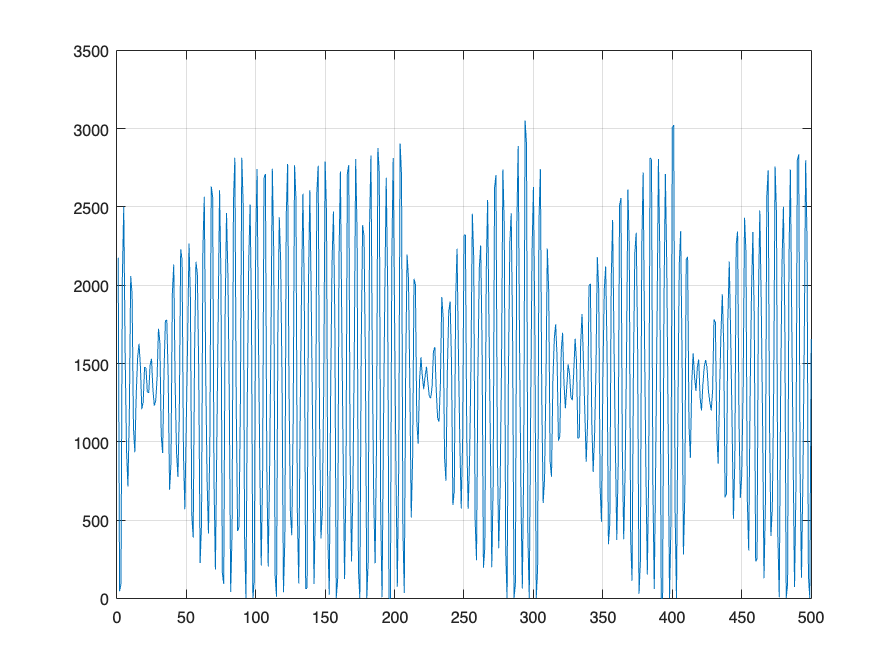

packet_length = dim(1)*dim(2);
transmit=reshape(transmit, packet_length, 1);
figure();
plot(transmit);

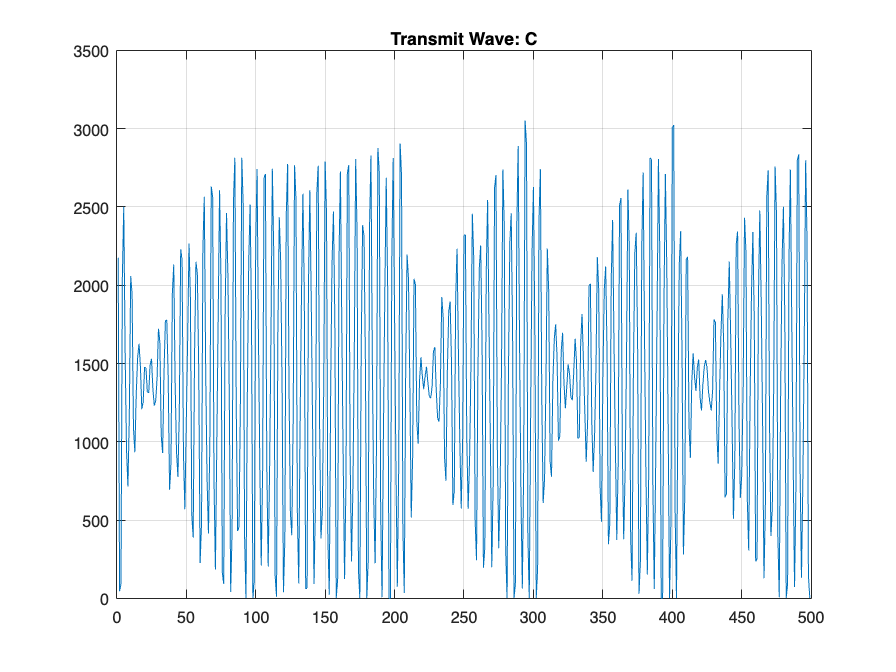

plot(transmit(1:end-1));
title("Transmit Wave: C");

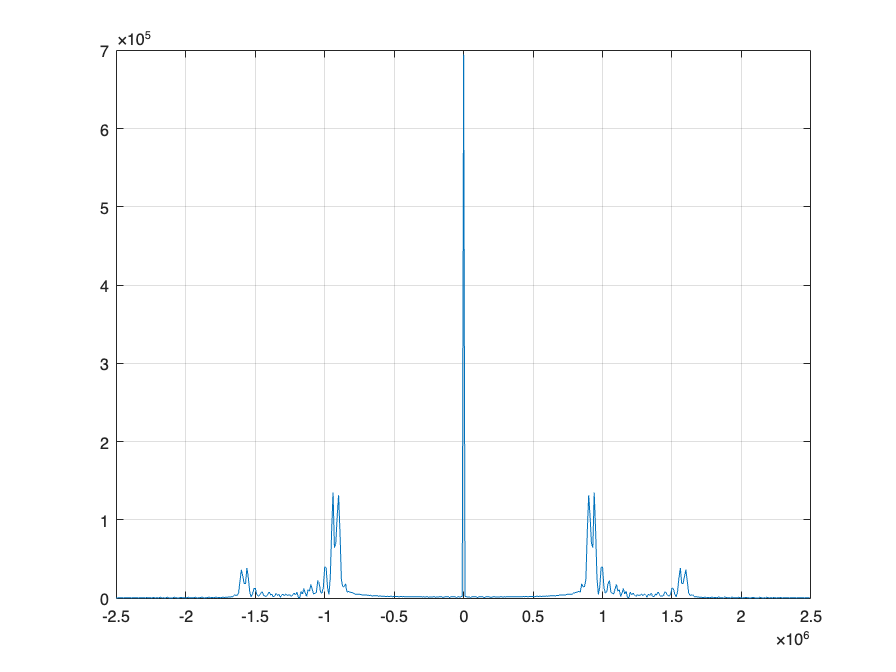

FS = 5000000;
spectrum = fftshift(fft(transmit));
freq = (-length(transmit)/2:length(transmit)/2 - 1)/length(transmit)*FS;
figure();
plot(freq, abs(spectrum))

## Normalize Wave

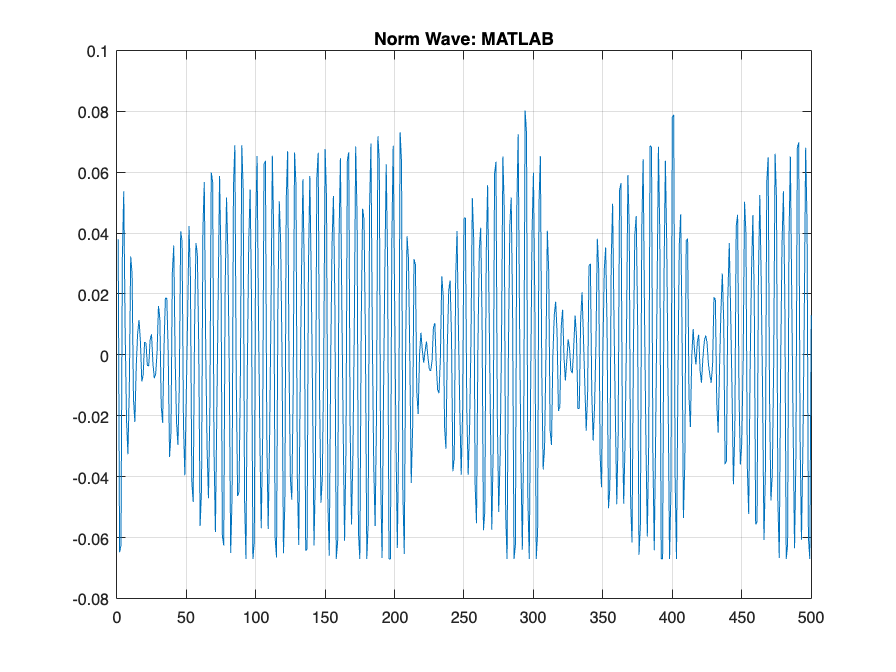

norm_wave_M = (transmit-mean(transmit))/std(transmit) /25;

figure();
plot(norm_wave_M);
title("Norm Wave: MATLAB");

## Costas Loop

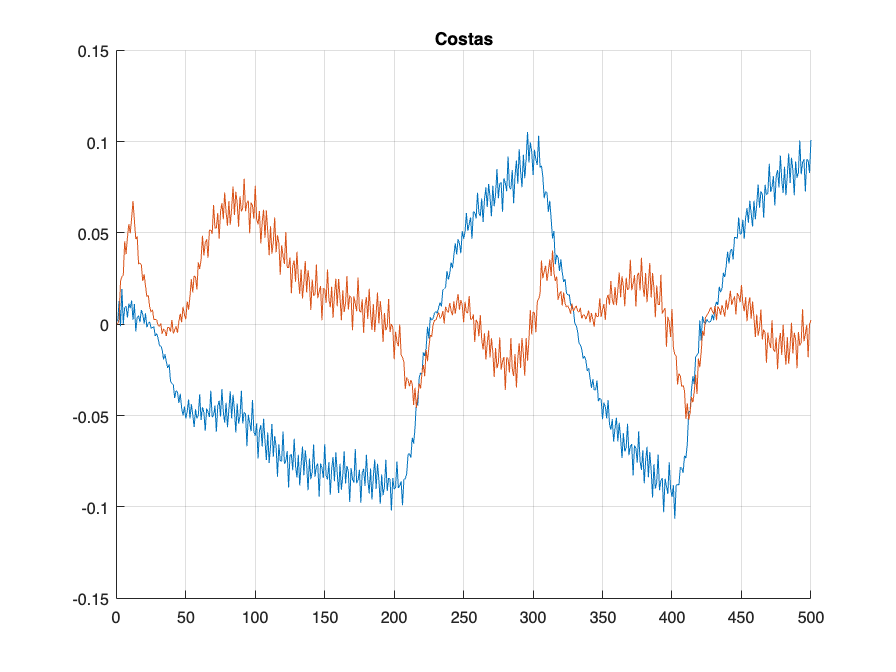

df = 0;%-50e3;
f0 = 940e3;%FC+df; %1.05e6; % estimated frequency
f = [0, 0.1, 0.15, 1];
a = [1, 1, 0, 0];
order = 11;
lp = firpm(order, f, a);

phase = 0;
inph = zeros(1, order+1);
quad = zeros(1, order+1);
inph_ = zeros(1, order+1);
quad_ = zeros(1, order+1);
error = 0;
% create lowpass as percent of this
%lp = [0.238053579626575	0.0644231488551473	0.0684583456734438	0.0684583456734438	0.0644231488551473	0.238053579626575];
integrator = 0;

kp = 8.5;
ki = 0.1;

for i = order+1:packet_length+order
    k = i - order;
    c = 2*cos(2*pi*f0/FS*(k-1)+phase);
    s =-2*sin(2*pi*f0/FS*(k-1)+phase);
    % demodulate the signal by mixing with NCO signals
    inph_(order+1) = norm_wave_M(k) * c;
    quad_(order+1) = norm_wave_M(k) * s;
    % low pass filter to get rid of high frequency components
    I = filter(lp, 1, inph_);
    Q = filter(lp, 1, quad_);
    inph(k) = I(order+1);
    quad(k) = Q(order+1);
    
    inph_(1:end-1) = inph_(2:end);
    quad_(1:end-1) = quad_(2:end);
    
    % mix in_ph and quad to get error signal
    error = I(order+1) * Q(order+1);
    
    % NCO
    integrator = integrator + ki * error;
    phase = phase+kp*error+integrator;
end

figure();
hold on;
plot(inph);
plot(quad);
title('Costas');
hold off;

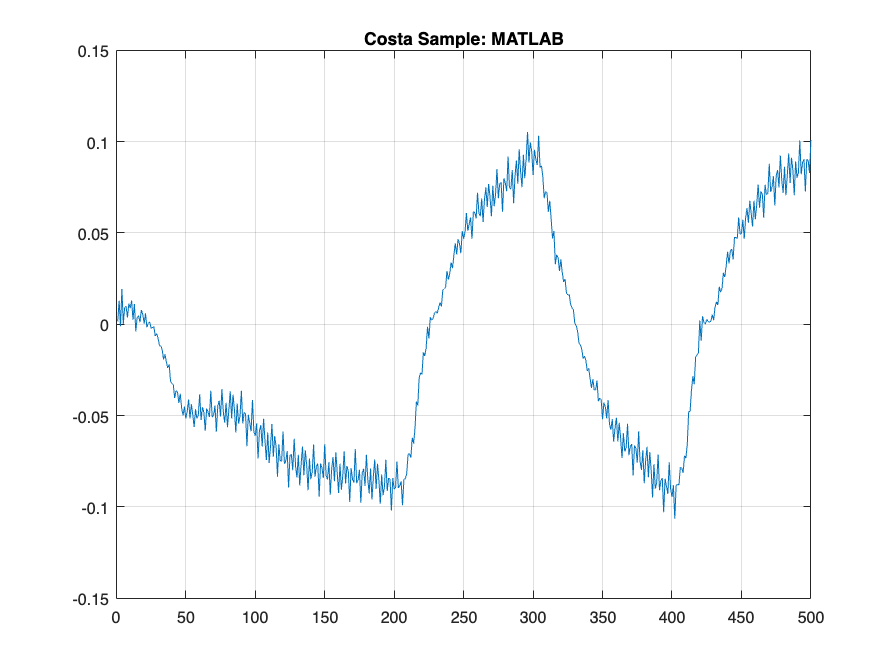


figure();
plot(inph);
title("Costa Sample: MATLAB");

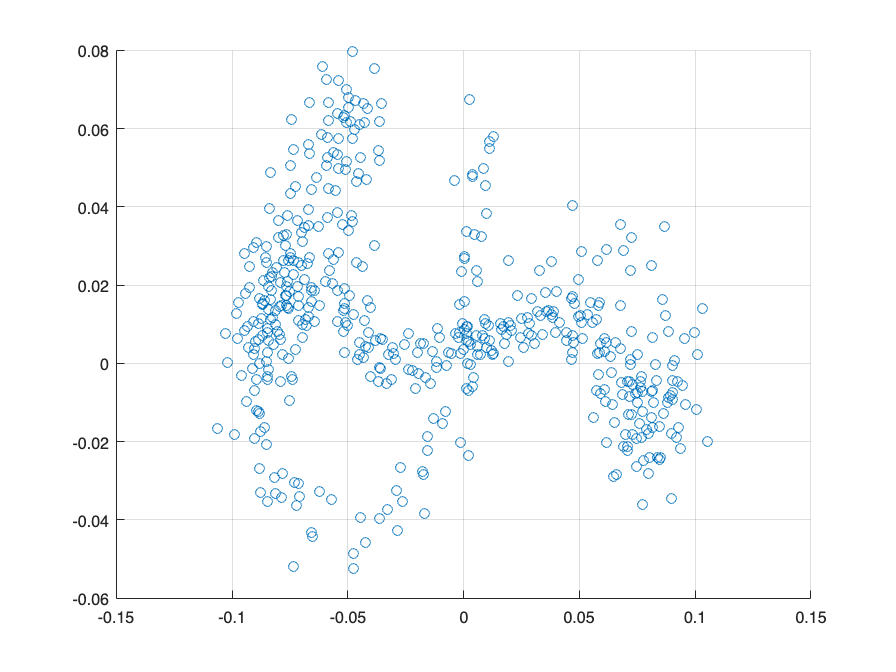

figure()
scatter(inph, quad)

## SRRC filtering

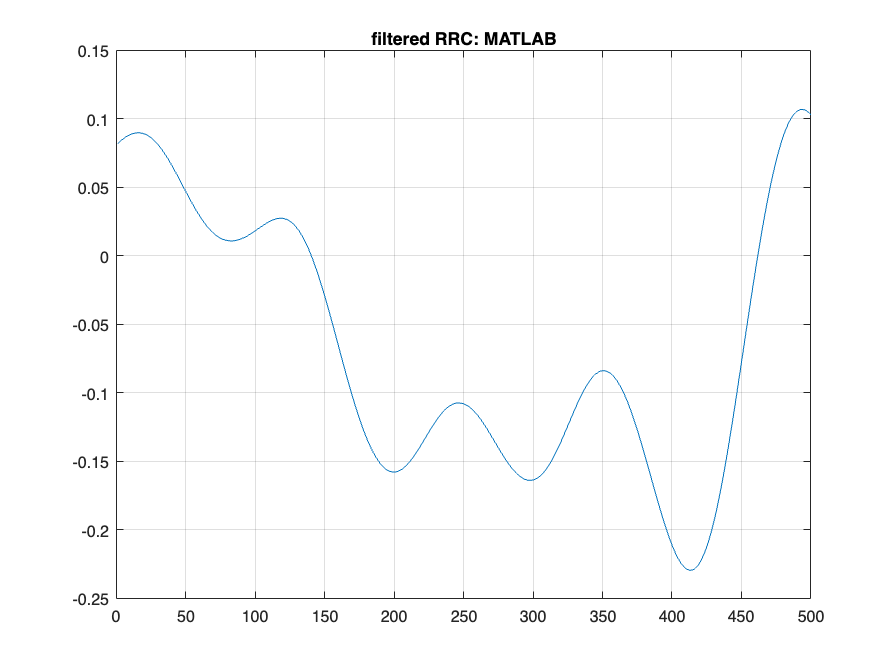

filtered_samps_M = conv(inph, RRC, 'same');
figure();
plot(filtered_samps_M);
title("filtered RRC: MATLAB");

filtered_samps_M = inph;

## Timing Recovery

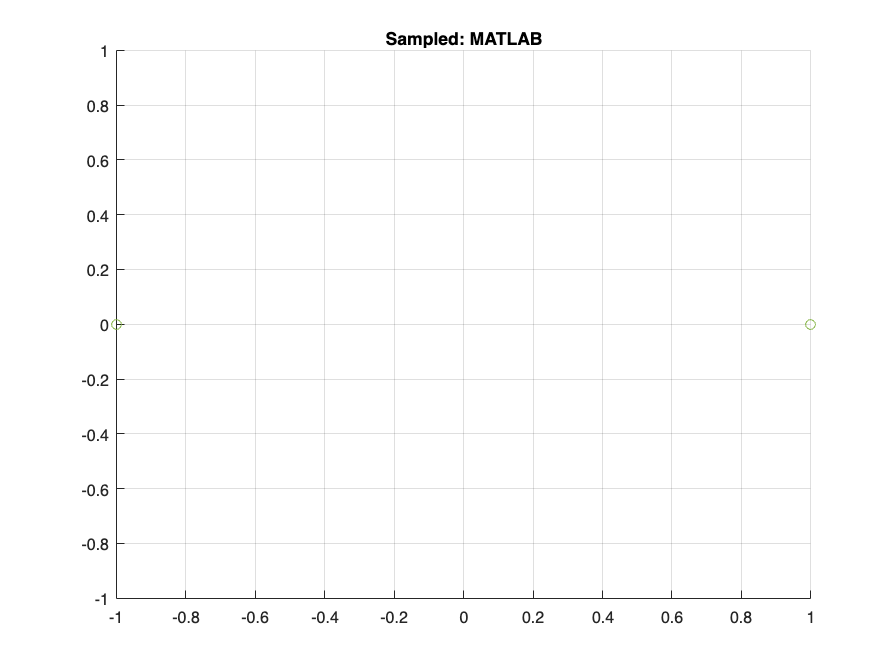

i = filtered_samps_M;
q = quad;
%create zero crossing signal
zero_cross = ~(sign(i(1:end-1).*i(2:end))+1);

%PLL clock recovery pll
Kp_PLL = 0.01;
Ki_PLL = 0.05;
prev_acc = -0.00001;
real_samp = [];
quad_samp=[];
err = [];
integrator = sps;
for k = 1:packet_length-1
    phase_acc = prev_acc + 2*pi/sps;
    %Check if we have crossed zero on the phase accumulator
    %If the previous value was around -pi and the current value is around pi - we crossed it.
    p1 = wrapToPi(phase_acc);
    p2 = wrapToPi(prev_acc);
    if (p1< -pi * 0.75 && p2 > pi*0.75)
        %we have crossed zero - sample
        real_samp(end+1) = i(k);
        quad_samp(end+1) = q(k);
    end
    %Detect zero crossing and use it to tune PLL
    if (zero_cross(k))
        %we have a zero crossing - adjust freq
        err(end+1) = wrapToPi(phase_acc);
        integrator = integrator + err(end)*Ki_PLL;
        sps = err(end) * Kp_PLL + integrator;
    end
    prev_acc = phase_acc;
end

figure();
sampled_M = sign(real_samp);
scatter(sampled_M, zeros(length(real_samp)));
title("Sampled: MATLAB");


%{
figure();
plot (real_samp);
hold on;
plot(quad_samp);
hold off;
selected = real_samp +1j*quad_samp;
legend("Real sampled", "Imaginary sampled");
scatterplot(real_samp+quad_samp*1j);
figure;
plot(err);
legend("PLL error");
%}